# **Evaluación 1 | Procesamiento de señales e imágenes 2023-1**

*Estudiante: Nícolas Farfán Cheneaux*

*Profesor: Max Chacón*

*Ayudante: Luis Corral*

### Pregunta 1

Para calcular la frecuencia alias (fa) usando herramientas del dominio del tiempo, se seguirán los siguientes pasos:

1) Identificar los picos de la señal con la función **findpeaks.**

2) Calcular la distancia en tiempo entre los picos de la señal.

3) Se obtiene el **periodo** y a partir de este, la **frecuencia**.


% Se lee el archivo de audio de la señal
[x_n,Fs] = audioread('senal_1.wav');

% Visualización de la frecuencia de muestreo (150Hz)
Fs

Fs = 150

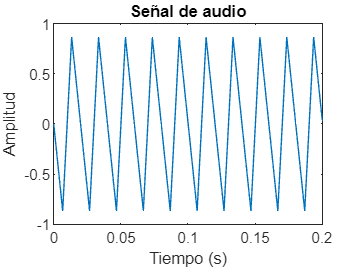


% Visualizar la señal en el dominio del tiempo
d = length(x_n)/Fs;
t = linspace(0, d,length(x_n));
figure;
plot(t,x_n);
xlim([0 0.2]); % Se acota para visualizar de manera clara
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal de audio');


% Calculo de la frecuencia alias usando herramientas del domino del tiempo (fa)

% Se indentifican los picos de la señal
[pks, locs] = findpeaks(x_n);

% Se calcula la distancia en el tiempo entre los picos de la señal
time_diff = diff(locs)/Fs;
periodo = mean(time_diff)

periodo = 0.0200


% Se obtiene la frecuencia de la señal
fa = 1/periodo;
disp(['La frecuencia alias de la señal es ', num2str(fa), ' Hz']);

La frecuencia alias de la señal es 50 Hz


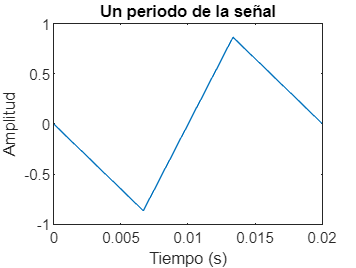


% Gráficamente podemos comprobar viendo un periodo de la señal
plot(t,x_n);
xlim([0 periodo]);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Un periodo de la señal');


% Calculo de la frecuencia muestreada originalmente (f)
% f = |fa - Fs [fa / Fss]|
f = abs(fa - Fs*ceil(fa/Fs))

f = 0

disp(f)

     0



disp(['La frecuencia original es ', num2str(f), ' Hz']);

La frecuencia original es 0 Hz


Cómo se puede observar la frecuencia muestrada originalmente, efectivamente se encuentra en el intervalo:

 
$$\begin{array}{l}
\frac{\mathrm{Fs}}{2}\le f\le \mathrm{Fs}\\
\frac{75}{2}\le 100\le 150\\
35\le 100\le 150
\end{array}$$


Se satisface la desigualdad, por lo que la frecuencia original f es **100Hz.**

### Pregunta 2

El filtro de tipo Butterworth posee la siguiente transformada z de su ecuación de diferencia, la cual es la función Transferencia del sistema H(z):

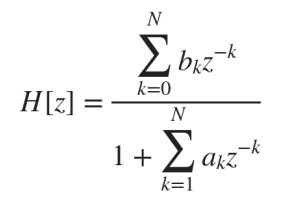

Dado que se tiene N = 2.

Se desarrolla la sumatoria y se obtienen los siguientes coeficientes:

H(z) = $\frac{b_0 z^0 +b_1 z^{-1} +b_2 z^{-2} }{1+a_1 z^{-1} +a_2 z^{-2} }=\frac{b_0 z^2 +b_1 z^1 +b_2 z^0 }{z^2 +a_1 z^1 +a_2 z^0 }$

clearvars
[x_n,Fs] = audioread('1kHz_44100Hz_16bit_05sec.wav'); % Lectura del archivo de la señal

% Frecuencia de muestreo
Fs

Fs = 44100


% Frecuencia de corte del filtro
fc = 800

fc = 800


% Fr
Fr = Fs / fc

Fr = 55.1250


% Función de transferencia
% Dado que H[z] = Y[z] / X[z]

% Cálculo de los coeficientes numerador
a1 = (2*(tan(pi/Fr)^2-1)) / (1 + (2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2))

a1 = -1.8391

a2 = (1-2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)/(1+2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)

a2 = 0.8511


% Cálculo de los coeficientes denominador
b2 = (tan(pi/Fr)^2)/(1+2*cos(pi/4)*tan(pi/Fr)+tan(pi/Fr)^2)

b2 = 0.0030

b0 = b2

b0 = 0.0030

b1 = 2*b0

b1 = 0.0060


% Vector de coeficientes numerador
b = [b0 b1 b2]

b =     0.0030    0.0060    0.0030



% Vector de coeficientes denominador
a = [1 a1 a2]

a =     1.0000   -1.8391    0.8511



% Visualización de la entrada del sistema x[n]
x_n

x_n =          0
    0.0982
    0.1945
    0.2867
    0.3733
    0.4522
    0.5219
    0.5811
    0.6286
    0.6632



% Obtención de la respuesta al impulso h[n]
h_n = impz(b, a)

h_n =     0.0030
    0.0115
    0.0216
    0.0300
    0.0368
    0.0421
    0.0461
    0.0489
    0.0508
    0.0517



% Obtención de la salida del sistema y[n]
y_n = conv(x_n, h_n, "same")

y_n =     0.1843
    0.2287
    0.2683
    0.3023
    0.3302
    0.3513
    0.3652
    0.3716
    0.3705
    0.3618


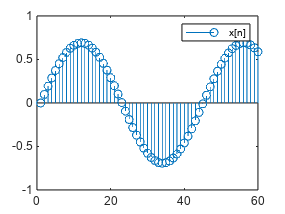


% Gráfico entrada del sistema x[n]
stem(x_n)
legend('x[n]')
xlim([0 60]);
ylim([-1 1]);

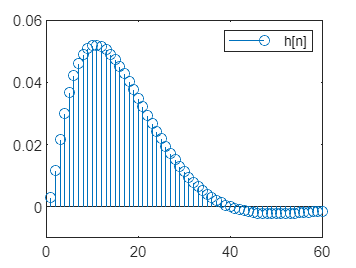


% Gráfico respuesta al impulso h[n]
stem(h_n)
legend('h[n]')
xlim([0 60]);
ylim([-0.01 0.06]);

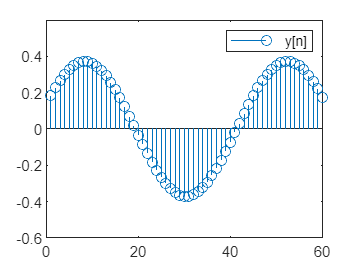


% Gráfico salida del sistema y[n]
stem(y_n)
legend('y[n]')
xlim([0 60]);
ylim([-0.6 0.6]);

### Pregunta 3

Se aplica la transformada Z a la ecuación de diferencias y se obtiene:


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +\alpha y\left\lbrack n-1\right\rbrack \\
Y\left(z\right)=X\left(z\right)+\alpha \;Y\left(z\right){\;z}^{-1} \\
Y\left(z\right)\;\left(1-\alpha z^{-1} \right)=X\left(z\right)
\end{array}$$


Función Transferencia del sistema H(z)

H(z) = $\frac{Y\left(z\right)}{X\left(z\right)}=\frac{1}{1-\alpha z^{-1} }=\frac{z}{z-\alpha \;}=\frac{z}{z-0\ldotp 6\;}$

clearvars
% Valor de alpha definido
alpha = 0.6

alpha = 0.6000


% Coeficiente del numerador
b = 1

b = 1


% Vector de coeficientes denominador
a = [1 -alpha]

a =     1.0000   -0.6000


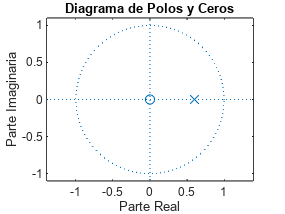


% Diagrama de Polos y Ceros
figure
zplane(b, a)
xlabel('Parte Real');
ylabel('Parte Imaginaria');
title('Diagrama de Polos y Ceros');

### Análisis del diagrama de polos y ceros

Como se puede apreciar en el diagrama de polos y ceros, tenemos un cero en el origen y un polo con **parte real positiva dentro del círculo**, por lo tanto el sistema es **estable**.